# Semantic Segmentation Using Deep Learning

**Copyright 2018 The MathWorks, Inc.**

## Motivation

The motivation for this example is to use Semantic Segmentation to detect the free space on the road as well as lanes and pavements. This will provide the necessary information for an autonomous driving mediated perception approach. This involves the recognition of multiple objects within the scene (cars, road, lanes etc.) so that an AI-based engine can perform accurate path-planning. To demonstrate this, we will train a deep CNN using the CamVid dataset, and we will provide visual and quantitative results proving the accuracy Semantic Segmentation. 

## Setup 

SegNet training is based on the VGG-16 network.  `vgg16 `returns a pretrained VGG-16 model. This model is trained on a subset of the ImageNet database [[1]](vgg16.html#bvo3twr-8), which is used in the ImageNet Large-Scale Visual Recognition Challenge (ILSVRC) [[2]](vgg16.html#bvo3twr-9). VGG-16 is trained on more than a million images and can classify images into 1000 object categories. For example, keyboard, mouse, pencil, and many animals. As a result, the model has learned rich feature representations for a wide range of images.

This function requires Neural Network Toolbox Model *for VGG-16 Network *support package. If this support package is not installed, then the function provides a download link.

% Download and install Neural Network Toolbox Model for VGG-16 Network support package.
vgg16;

## Download CamVid Dataset [3]

Download the CamVid (Cambridge-driving Labeled Video) Database from the following URLs:

imageURL = 'http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/files/701_StillsRaw_full.zip';
labelURL = 'http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/data/LabeledApproved_full.zip';


% Set the outputFolder to be on the current path
outputFolder = fullfile(pwd, 'CamVid');

if ~exist(outputFolder, 'dir')
    disp('Downloading 557 MB CamVid data set...');
    
    unzip(imageURL, fullfile(outputFolder,'images'));
    unzip(labelURL, fullfile(outputFolder,'labels'));
end

Note: Download time of the data depends on your internet connection. The commands used above will block MATLAB until the download is complete. Alternatively, you can use your web browser to first download the dataset to your local disk. To use the file you downloaded from the web, change the `outputFolder` variable above to the location of the downloaded file.

## Resize the data

The images in the CamVid data set are 720 by 960. To reduce training time and memory usage, resize the images and pixel label images to 360 by 480. It takes approximately 104 seconds for all the images and labels.

imgDir = fullfile(outputFolder,'images','701_StillsRaw_full');
labelDir = fullfile(outputFolder,'labels');
HelperFunctions.prepareData(imgDir,labelDir);

Image data already resized
Label data already resized


## References

[1] Badrinarayanan, Vijay, Alex Kendall, and Roberto Cipolla. "SegNet: A Deep Convolutional Encoder-Decoder Architecture for Image Segmentation." arXiv preprint arXiv:1511.00561, 2015.

[2] Brostow, Gabriel J., Julien Fauqueur, and Roberto Cipolla. "Semantic object classes in video: A high-definition ground truth database." Pattern Recognition Letters Vol 30, Issue 2, 2009, pp 88-97.

[3] G.J. Brostow, J. Fauqueur, R. Cipolla, "Semantic object classes in video: A high-definition ground truth database" , Pattern Recognition Letters 30(2): 88-97, 2009

## Load CamVid Images 

Use `imageDatastore` to load CamVid images. The `imageDatastore` enables you to efficiently load a large collection of images on disk. It creates a datastore from the collection of image data specified by `location`. A datastore is a repository for collections of data that are too large to fit in memory. After creating an `ImageDatastore `object, you can read and process the data in various ways. 

% Get the full path for the folder containing all the raw images
imgDir = fullfile(outputFolder,'images','701_StillsRaw_full');

% Load the images located in the above path using imageDatstore - ML Function
imds = imageDatastore(imgDir);

Display one of the images.

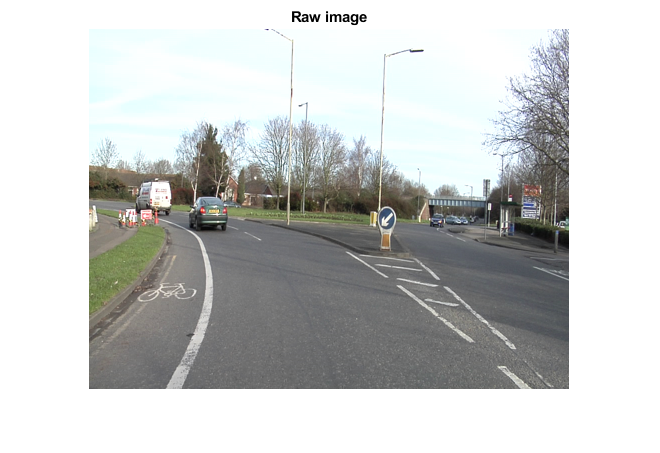

% Suppress image display warnings
warning('off','images:initSize:adjustingMag')

pic_num = 125;
I_raw = readimage(imds, pic_num);

% Because images are dark histogram equalization is performed. - Image Processing toolbox
I = histeq(I_raw); 

figure
imshow(I_raw)
drawnow
title('Raw image')

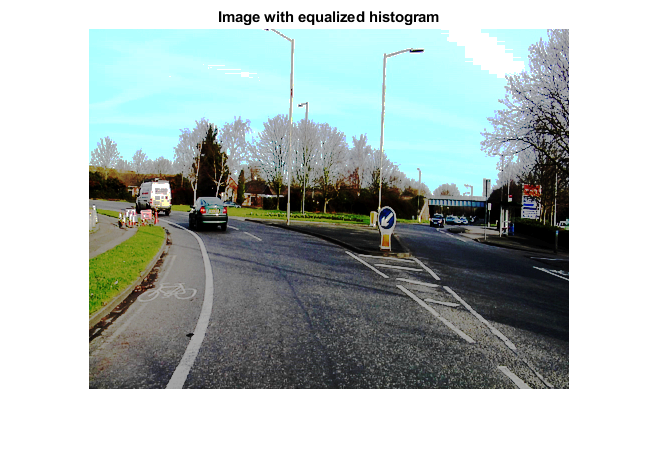

figure
imshow(I)
drawnow
title('Image with equalized histogram')

## Load CamVid Pixel Labeled Images

Use `pixelLabelDatastore` to load CamVid pixel label image data. A `pixelLabelDatastore` encapsulates the pixel label data and the label ID to class name mapping. Following the procedure used in original SegNet paper, the 32 original classes in CamVid will be reduced to the following 10:

classes = [
    "Tree"
    "Building"
    "FreeSpace"
% 
%     "Environment"
%     "Building"
%     "Pole"
%     "Road"
%     "Lane"
%     "Pavement"
%     "SignSymbol"
%     "Car"
%     "Pedestrian"
%     "Bicyclist"
    ];

To reduce 32 classes into 10, multiple classes from the orignal dataset are grouped together. For example, "Car" is a combination of "Car", "SUVPickupTruck", "Truck_Bus", "Train", and "OtherMoving". The grouped label IDs are returned by the supporting function `camvidPixelLabelIDs`, which is listed at the end of this example. In our labeled data, every pixel label ID is provided as an RGB color value. To associate the labels with the corresponding classes, we have to associate the RGB values with the corresponding class. 

labelIDs = HelperFunctions.camvidPixelLabelIDs();

Use the classes and labelIDs to create the `pixelLabelDatastore`. `pixelLabelDatastore` will associate the RGB values with the labels and so when an image is read, it will return a categorical array. It works in a similar way to an `imageDatastore `with the main difference that the labeling is not for a single object (i.e. a car in the image) but it is for each pixel individually. For this reason, the images containing the data and the images containing the labels need to have 1-1 correspondence  in the order they are read. That is why the filenames are usually the same with the labels have a _L suffix. 

ans = 26×26 categorical array
     FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace 
     FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace 
     FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      FreeSpace      Fre

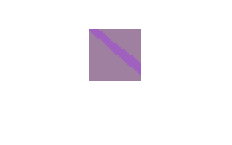

% Create the full path to the directory that contains the ground truth pictures.
labelDir = fullfile(outputFolder,'labels');

% This function works similarly to imageDatastore. Instead it returns a datastore object that can be used to read pixel label data. - Computer Vision System Toolbox
pxds = pixelLabelDatastore(labelDir,classes,labelIDs);

% Create a custom colormap to color each label in a different way
cmap = HelperFunctions.camvidColorMap;

% Show a ground-truth image
HelperFunctions.showImageMapping(pxds,cmap)

drawnow

Read and display one of the pixel labeled images by overlaying it on top of an image.

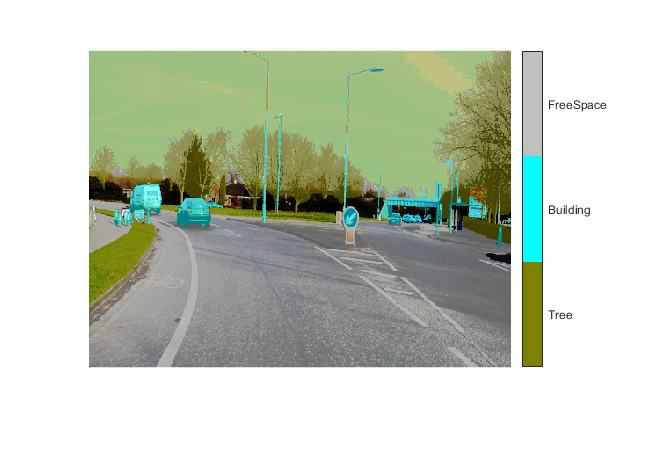

C = readimage(pxds, pic_num);

% Overlay segmentation results onto original image. - Computer Vision System Toolbox
B = labeloverlay(I,C,'ColorMap',cmap);

figure
imshow(B) 
drawnow
HelperFunctions.pixelLabelColorbar(cmap,classes);

## Dataset Statistics

To see the distribution of class labels in the CamVid dataset, use `countEachLabel[CVST]`. This counts the number of pixels by class label and returns a summary table of the labels in imds and the number of files associated with each. The reason that the total number of pixels differs from class to class, is because the function only counts images that contain the class in question. 

(The difference between the CVST `countEachLabel `and the one that basic ML has is the following: ML one counts files in ImageDatastore labels whereas the CVST one counts pixel labels for each class)

tbl = countEachLabel(pxds)

tbl = 3×3 table
        Name         PixelCount    ImagePixelCount
    _____________    __________    _______________

    {'Tree'     }    3.2708e+07      1.2096e+08   
    {'Building' }    4.1159e+07      1.2113e+08   
    {'FreeSpace'}    4.3613e+07      1.2113e+08   


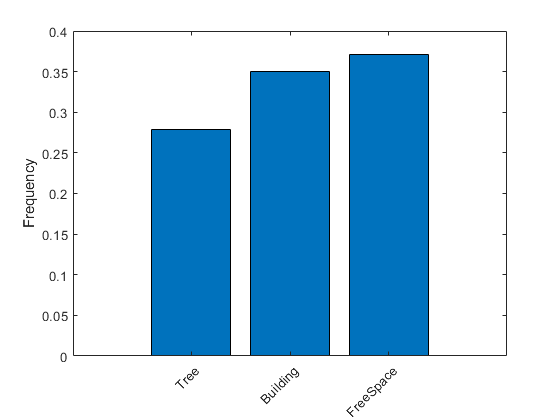

% We calculate the frequency in order to get a histogram of the data
frequency = tbl.PixelCount/sum(tbl.PixelCount);

figure
bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

Using this information we can see that the classes are not balanced and that some of the classes are rare. These classes can be difficult to learn and thus class balancing will be performed. 

# Preparation and Training of the Neural Network

## Prepare Training And Test Sets 

SegNet is trained using 60% of the images from the dataset. The rest of the images are used for testing. The following code randomly (using randperm) splits the image and pixel label data into a training (imdsTrain, pxdsTrain) and test set (imdsTest, pxdsTest).

[imdsTrain, imdsTest, pxdsTrain, pxdsTest] = HelperFunctions.partitionCamVidData(imds,pxds,labelIDs);

The 60/40 splits results in the following number of training and test images:

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 421

numTestingImages = numel(imdsTest.Files)

numTestingImages = 280

## Create The Network

Use `segnetLayers` to create a SegNet network initialized using VGG-16 weights. `segnetLayers` automatically performs the network surgery needed to transfer the weights from VGG-16 and adds the additional layers required for semantic segmentation.

imageSize = [360 480 3];
numClasses = numel(classes);

% segnetLayers returns SegNet network layers, lgraph, that is preinitialized with layers and weidghts from a pretrained model.
lgraph = segnetLayers(imageSize,numClasses,'vgg16');

% lgraph initially has 91 Layers. 
lgraph.Layers

ans =   91x1 Layer array with layers:

     1   'inputImage'        Image Input                  360x480x3 images with 'zerocenter' normalization
     2   'conv1_1'           Convolution                  64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'bn_conv1_1'        Batch Normalization          Batch normalization
     4   'relu1_1'           ReLU                         ReLU
     5   'conv1_2'           Convolution                  64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     6   'bn_conv1_2'        Batch Normalization          Batch normalization
     7   'relu1_2'           ReLU                         ReLU
     8   'pool1'             Max Pooling                  2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     9   'conv2_1'           Convolution                  128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
  

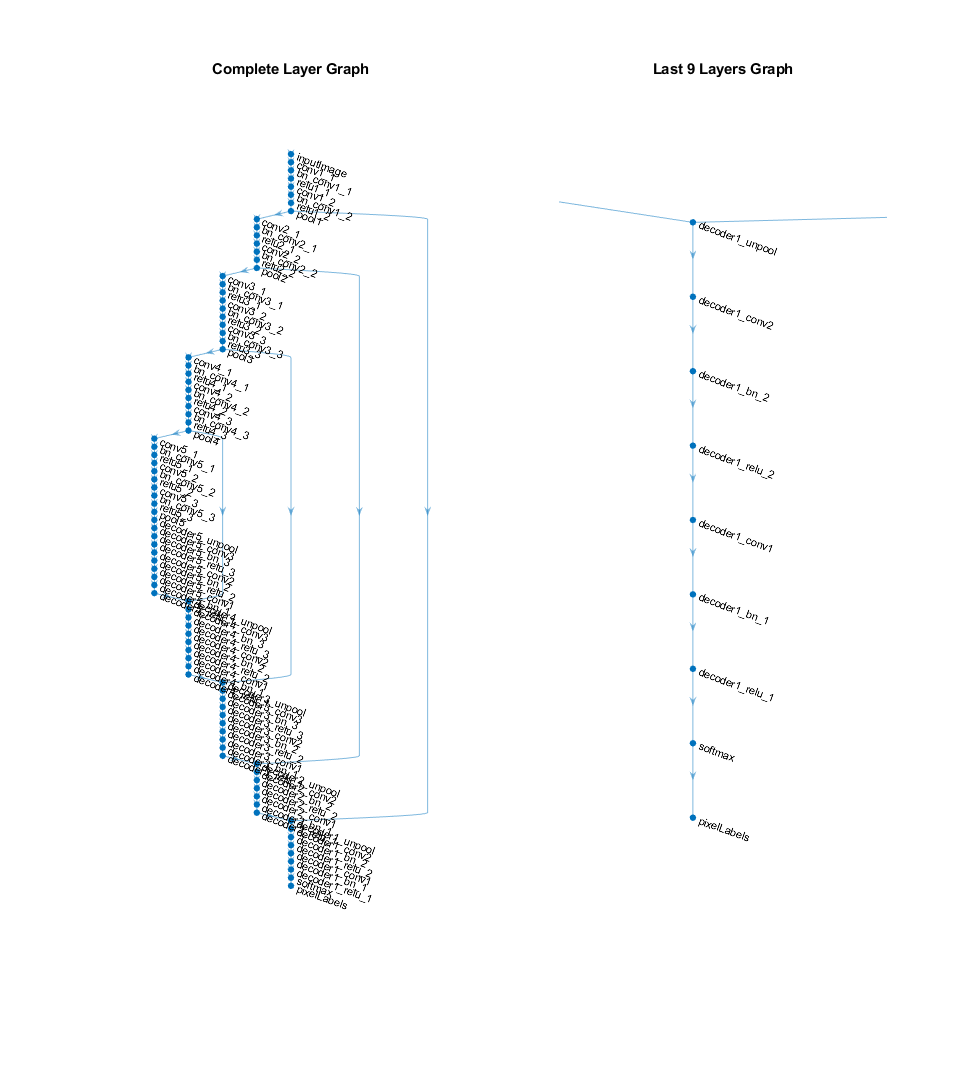

% Plot the 91-Layer lgraph 
fig1=figure('Position', [100, 100, 1000, 1100]);
subplot(1,2,1)
plot(lgraph);
axis off
axis tight
title('Complete Layer Graph')

subplot(1,2,2)
plot(lgraph);
xlim([2.862 3.200])
ylim([-0.9 10.9])
axis off 
title('Last 9 Layers Graph')

The image size is selected based on the size of the images in the dataset, and the number of classes is selected based on the classes in CamVid.

## Balance Classes Using Class Weighting

As shown earlier, the classes in CamVid are not balanced. To improve training, class weighting can be used to balance the classes. Use the pixel label counts computed earlier with `countEachLabel` and calculate the median frequency class weights [3].

% Get the imageFreq using the data from the countEachLabel function
imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;

% The higher the frequency of a class the smaller the classWeight
classWeights = median(imageFreq) ./ imageFreq

classWeights =     1.2566
    1.0000
    0.9437


Specify the class weights using a `pixelClassificationLayer`. We can use the pixel classification layer to provide a categorical label for each image pixel processed by a convolutional neural network (CNN). This layer will replace the last layer of our NN

pxLayer = pixelClassificationLayer('Name','labels','ClassNames', tbl.Name, 'ClassWeights', classWeights)

pxLayer =   PixelClassificationLayer with properties:

            Name: 'labels'
         Classes: [Tree    Building    FreeSpace]
    ClassWeights: [3×1 double]
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


Update the SegNet network with the new `pixelClassificationLayer`. This requires removing and adding the new layer. The `pixelClassificationLayer` is located at index 91 in `lgraph.Layers`. Remove it using `removeLayers`, add the new one using `addLayers`, and reconnect it using `connectLayers`.

The reason that connectLayers needs to be used is because we are working with a DAG-Network.

% Plot the 91-Layer lgraph 
fig2=figure('Position', [100, 100, 800, 600]);
subplot(1,2,1)
plot(lgraph);
xlim([2.862 3.200])
ylim([-0.9 10.9])
axis off 
title('Initial last 9 Layers Graph')

% Remove last layer of and add the new one we created. 
lgraph = removeLayers(lgraph, {'pixelLabels'});
lgraph = addLayers(lgraph, pxLayer);

% Connect the newly created layer with the graph. 
lgraph = connectLayers(lgraph, 'softmax','labels');
lgraph.Layers

ans =   91x1 Layer array with layers:

     1   'inputImage'        Image Input                  360x480x3 images with 'zerocenter' normalization
     2   'conv1_1'           Convolution                  64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'bn_conv1_1'        Batch Normalization          Batch normalization
     4   'relu1_1'           ReLU                         ReLU
     5   'conv1_2'           Convolution                  64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     6   'bn_conv1_2'        Batch Normalization          Batch normalization
     7   'relu1_2'           ReLU                         ReLU
     8   'pool1'             Max Pooling                  2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     9   'conv2_1'           Convolution                  128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
  

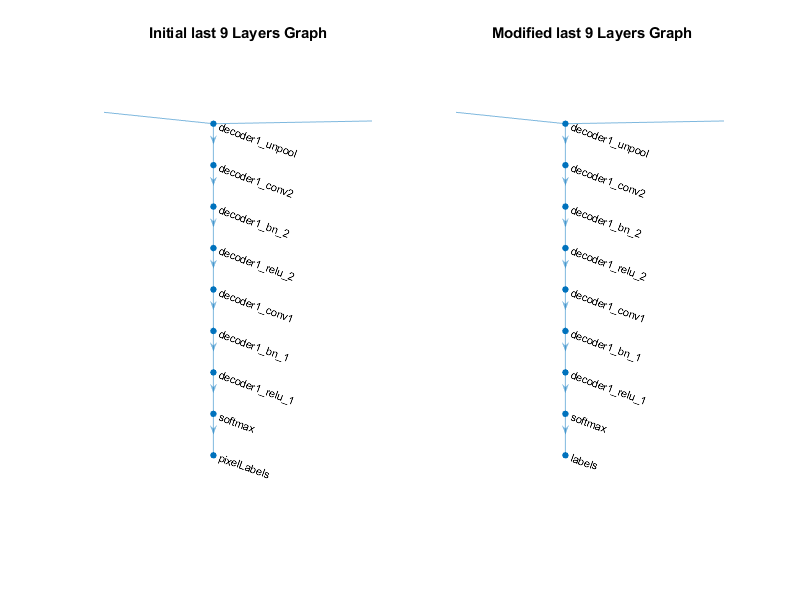

subplot(1,2,2)
plot(lgraph);
xlim([2.862 3.200])
ylim([-0.9 10.9])
axis off 
title(' Modified last 9 Layers Graph')

## Select Training Options

The optimization algorithm used for training is Stochastic Gradient Decent with Momentum (SGDM). Use `trainingOptions` to specify the hyper-parameters used for SGDM. 

During training, you can stop training and return the current state of the network by clicking the stop button in the top right corner. For example, you might want to stop training when the accuracy of the network reaches a plateau and it is clear that the accuracy is no longer improving. Once the execution is stopped, the script will continue executing. You cannot resume the training from where it stopped. 

A mini-batch size of 4 is used to reduce memory usage while training. This can be increased or decreased based on the amount of GPU memory you have on your system.

options = trainingOptions('sgdm', ... % This is the solver's name; sgdm: stochastic gradient descent with momentum
    'Momentum', 0.9, ...              % Contribution of the gradient step from the previous iteration to the current iteration of the training; 0 means no contribution from the previous step, whereas a value of 1 means maximal contribution from the previous step.
    'InitialLearnRate', 1e-2, ...     % low rate will give long training times and quick rate will give suboptimal results 
    'L2Regularization', 0.0005, ...   % Weight decay - This term helps in avoiding overfitting
    'MaxEpochs', 4,...              % An iteration is one step taken in the gradient descent algorithm towards minimizing the loss function using a mini batch. An epoch is the full pass of the training algorithm over the entire training set.
    'MiniBatchSize', 10, ...           % A mini-batch is a subset of the training set that is used to evaluate the gradient of the loss function and update the weights.
    'Shuffle', 'every-epoch', ...     % Shuffle the training data before each training epoch and shuffle the validation data before each network validation.
    'Verbose', false,...        
    'Plots','training-progress');   

## Data Augmentation

Data augmentation is used during training to provide more examples to the network because it helps improve the accuracy of network. Here, random left/right reflection and random X/Y translation of +/- 10 pixels is used for data augmentation. By performing data augmentation the training set is increased by creating and using synthetic data. A simple example would be the training of handwriting. Every letter\number can be skewed or wrapped so the training set can be increased and thus capture the hand-writing variability of different people. 

Use the `imageDataAugmenter` to specify these data augmentation parameters:

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation', [-10 10], 'RandYTranslation',[-10 10]);

There are several other types of data augmentation supported by `imageDataAugmenter`. Choosing amongst them requires empirical analysis and is another level of hyper-parameter tuning. 

The data augmentation process can also include the rotation of the image. While rotating, a portion of the image is going to be cropped and the values of the Data\Label images are going to be interpolated. An example of that can be seen in the following figure:

%HelperFunctions.showRotationEffect(imds,pxds,pic_num,30);

Even though the images is rotated and the values of the images interpolated, the pixel labeling remains the same. 

## Start Training

The training data and data augmentation selections are combined using `pixelLabelImageDatasource`. The pixelLabelDataImageDatasource reads batchs of training data, applies data augmentation, and sends the augmented data to the training algorithm.

datasource = pixelLabelImageSource(imdsTrain,pxdsTrain,...
    'DataAugmentation',augmenter);

Start training using `trainNetwork.` This network was trained on an NVIDIA(TM) Tesla K40c.The training times may be longer depending on your GPU hardware.

To train the network with the options set above, the training process will take approximately 19 hours. The number of iterations and the mini batch size are the two most contributing factors to that time. If we decrease the number of iterations by 20, the training takes approximately 10.5 hours. When the mini-batch size is increased, the training time will go down since the GPU (or CPU) will process more data at the same time. By increasing it by 1, the 19 hours become 12 hours. Finally, the learning rate can affect the training time. Approximately, for every order of magnitude we decrease the learning rate (0.1 -> 0.01) half an hour will be added to the total training time. 

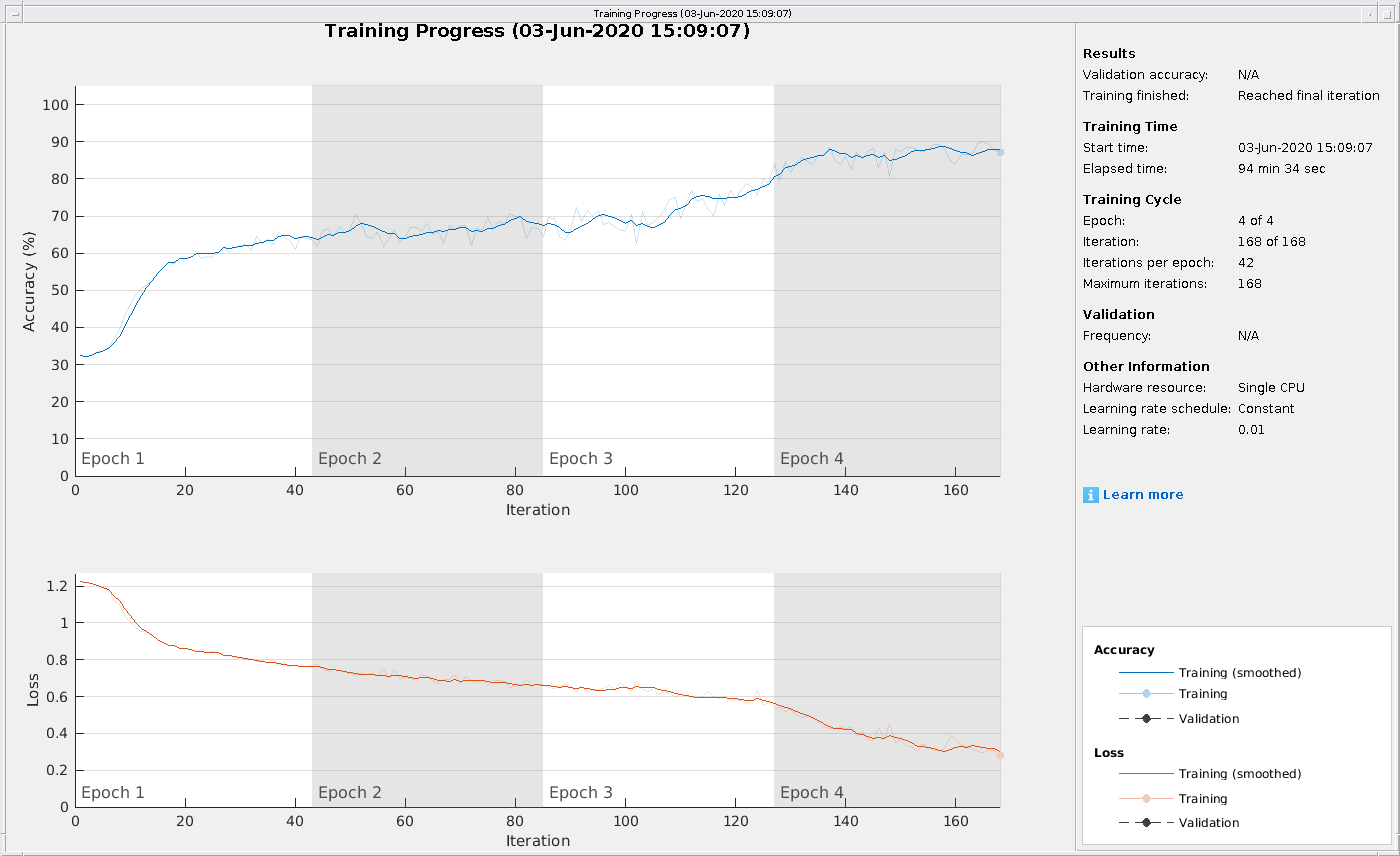


% To avoid having to re-train, you can use the pretrained model
% Contact image-processing@mathworks.com for access

% Trains a network for image classification problems
tic
[net, info] = trainNetwork(datasource,lgraph,options);

toc

Elapsed time is 6306.047725 seconds.


save('PreTrainedCnn.mat','net','info','options');
disp('NN trained');

NN trained


The above network will have 90% accuracy on the training set. The metric for that accuracy is: how many pixel labels were predicted right divided by total number of pixels. To do that we sum over height and width for all images in the batch and we divide by the total number of images in that batch.

## Show the image used on the beginning of the example

In the following example, we can see that the predicted image does a pretty good job in detecting the left most lane versus the ground truth. This is because the data was labeled by users and due to that, we can have intra and inter-observer variability. This means that even if I put the same user to tag the same data twice, the labeling will not be the same. In this case, we can see that the semantic segmentation outperforms the ground truth. 

The issue with this lies in the metrics. When we calculate the metrics for the accuracy of the prediction, the correctly predicted lane will count as a false positive thus leading to low IOU. By observing the results visually, we can see that this is not the case and that we can have confidence on the results of the semantic segmentation. This phenomenon is observed when the overall acuracy of our Neural Network is above 80%.

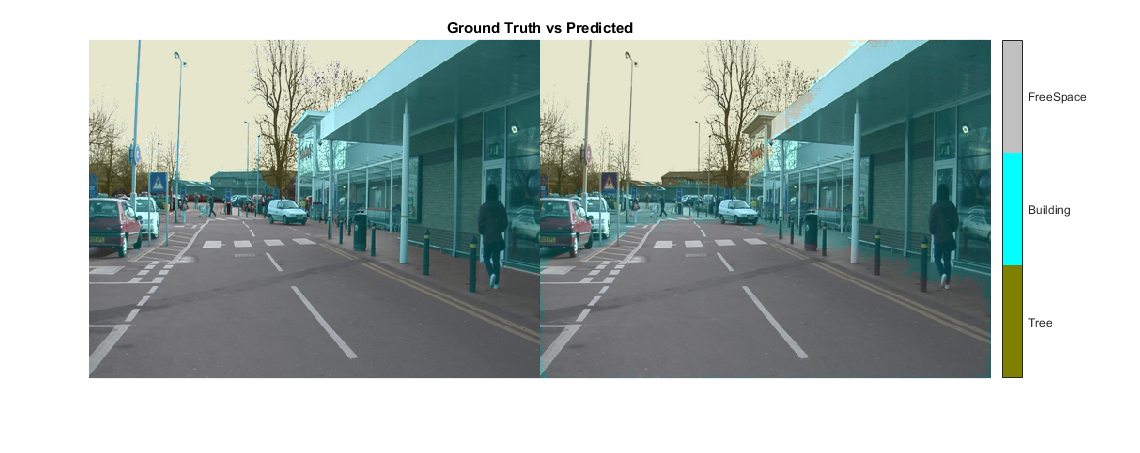

pic_num = 200;
I = readimage(imds, pic_num);
Ib = readimage(pxds, pic_num);

IB = labeloverlay(I, Ib, 'Colormap', cmap, 'Transparency',0.8);
figure
% Show the results of the semantic segmentation
C = semanticseg(I, net);
CB = labeloverlay(I, C, 'Colormap', cmap, 'Transparency',0.8);
figure
imshowpair(IB,CB,'montage')
HelperFunctions.pixelLabelColorbar(cmap, classes);
title('Ground Truth vs Predicted')

## Test Network On One Image

As a quick sanity check, run the trained network on one test image (1.74 seconds) using `semanticseg `[CVST]. 

I = read(imdsTest);

C = semanticseg(I, net);

Display the results.

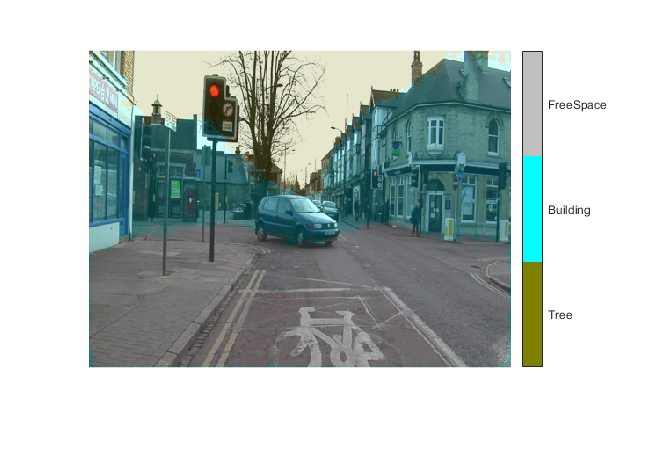

B = labeloverlay(I, C, 'Colormap', cmap, 'Transparency',0.8);
figure
imshow(B)
HelperFunctions.pixelLabelColorbar(cmap, classes);

Compare the results in `C` with the expected ground truth stored in `pxdsTest`. The important thing to note here is that although the semantic segmentation results do not have the granularity of the ground truth (ex. the persons in the image; They look like blobs instead of people), it is able to detect the objects in the correct position and label them accordingly. Due to that, the predicted labels contain a lot of False Positives. But, in a safety critical system such as Automated Driving, the ability to detect pedestrians, bicycles etc, makes the False Positives acceptable.

# Test on video

v = VideoReader("TestSemanticVideo.mp4");

numberOfFramesInspected = [1300:100:2000]

numberOfFramesInspected =         1300        1400        1500        1600        1700        1800        1900        2000


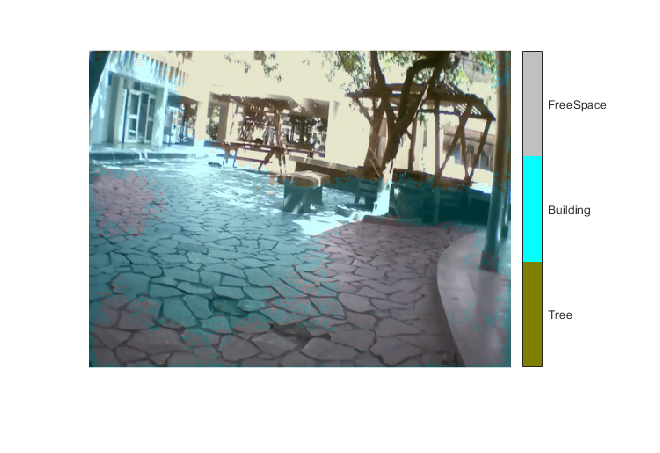

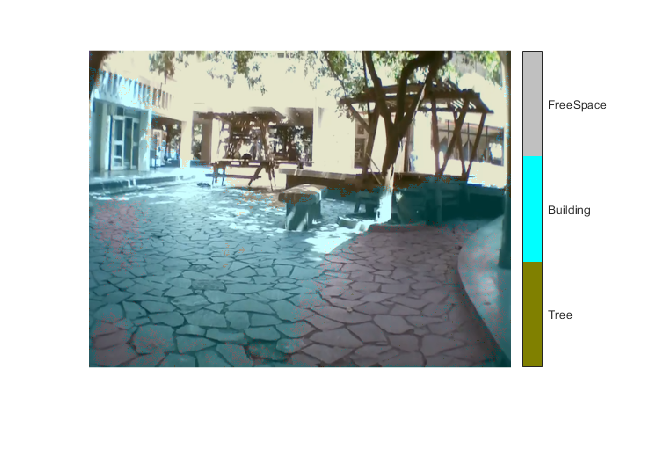

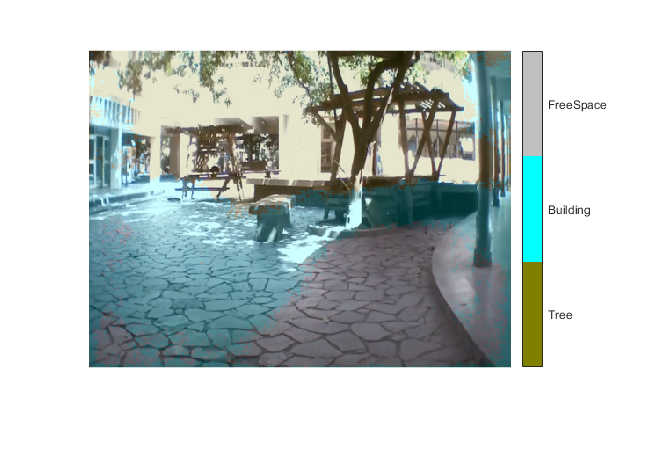

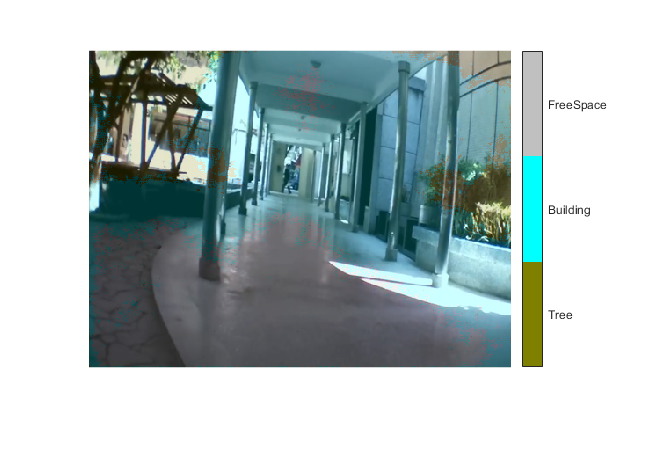

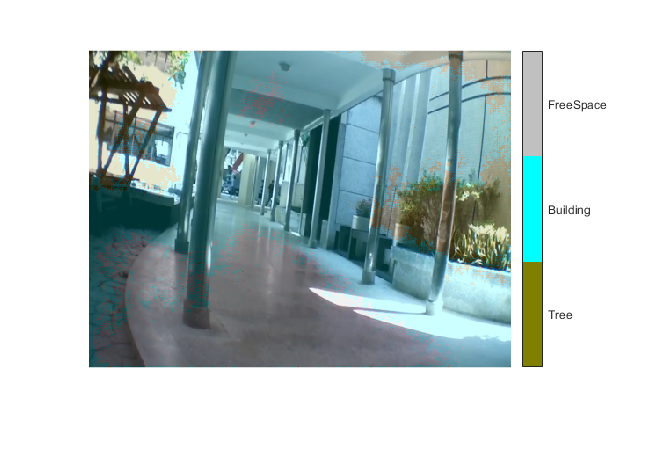

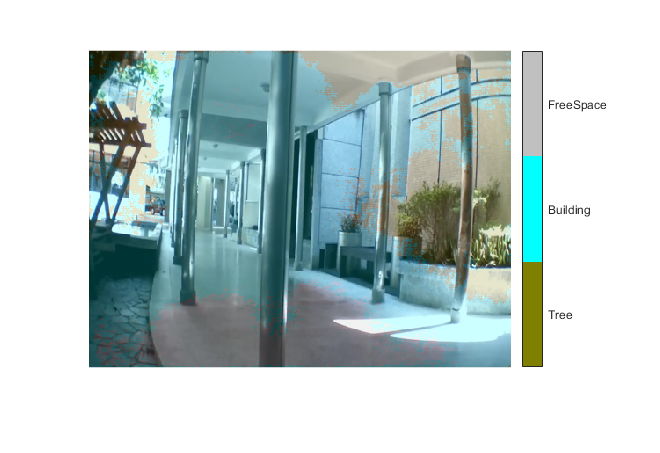

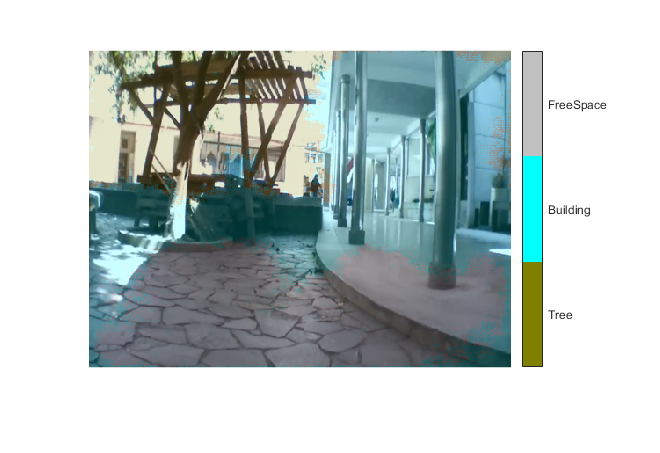

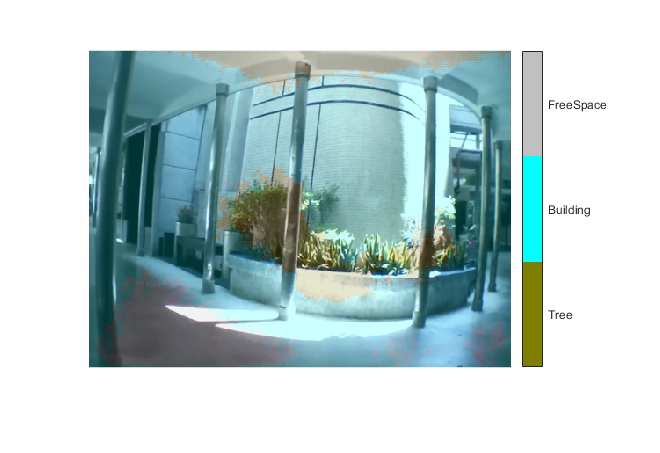


for i = 1 : length(numberOfFramesInspected)
    frame = read(v,numberOfFramesInspected(i));
    frame =  imresize(frame,[360 480]);
    C = semanticseg(frame, net);  
    B = labeloverlay(frame, C, 'Colormap', cmap, 'Transparency',0.8);
    figure
    imshow(B)
    HelperFunctions.pixelLabelColorbar(cmap, classes);
        
end 




% expectedResult = read(pxdsTest);
% 
% expected = uint8(expectedResult);
% predicted = uint8(C);
% 
% % Compare differences between images - Image Processing toolbox
% imshowpair(expected, predicted, 'montage')
% title('Ground Truth labels vs Predicted labels')

Visually, the semantic segmentation results overlap well for classes such as road, sky, and building. However, smaller objects like pedestrians and cars are not as accurate.The amount of overlap per class can be measured using the intersection-over-union (IoU) metric, also known as the Jaccard index. Use the [jaccard](docid:jaccard) function to measure IoU.

% % Jaccard similarity coefficient for image segmentation - Image Processing Toolbox
% iou = jaccard(C, expectedResult);
% 
% table(classes,iou)

Other common segmentation metrics include the [Dice index ](http://doc('dice'))and the [Boundary-F1](http://doc('bfscore')) contour matching score.

## Evaluate Trained Network 

To measure accuracy for multiple test images, run `semanticseg` on the entire test set. 

If CPU is used it takes 1h 49 mins.

If GPU is used it takes 7.2 minutes. 

% doTest = false;
% if doTest
%     pxdsResults = semanticseg(imdsTest,net,'WriteLocation',tempdir,'Verbose',false);

`semanticseg` returns the results for the test set as a `pixelLabelDatastore` object. The actual pixel label data for each test image in `imdsTest` is written to disk in the location specified by the 'WriteLocation' parameter. Use `evaluateSemanticSegmentation` measure semantic segmentation metrics on the test set results. It takes 32 seconds to run this command. 

% % Evaluate semantic segmentation data set against ground truth
%     metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',false);
% else
%     warning off MATLAB:datastoreio:pathlookup:fileNotFound
%     load('metrics.mat')
% end

`evaluateSemanticSegmentation` returns various metrics for the entire dataset, for individual classes, and for each test image. To see the dataset level metrics inspect metrics.DataSetMetrics.

% metrics.DataSetMetrics

The dataset metrics provide a high-level overview of the network performance. To see the impact each class has on the overall performance, inspect the per-class metrics using `metrics.ClassMetrics`.

% metrics.ClassMetrics

Although the overall dataset performance is quite high, the class metrics shows that underrepresented classes such as pedestrians, bicycles, and cars are not segmented as well as the larger classes such as road, and building. Additional data that includes more samples of the underrepresented classes may help improve the results.